# 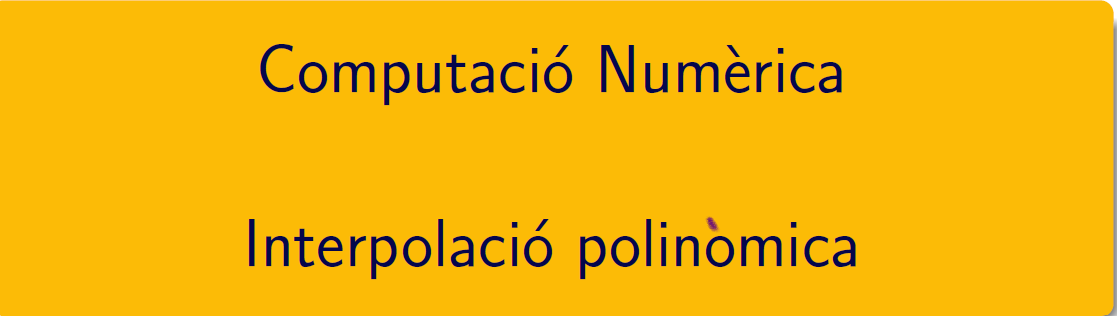

================================================================================

# Pràctica 9. Interpolació polinòmica i ajust de dades

## Introducció

Els exercicis d'aquest script són del document Guia-Lab9.pdf, podeu trobar més exercicis en CN_full6.pdf, disponibles en el campus virtual. 

### Exercici 1

### 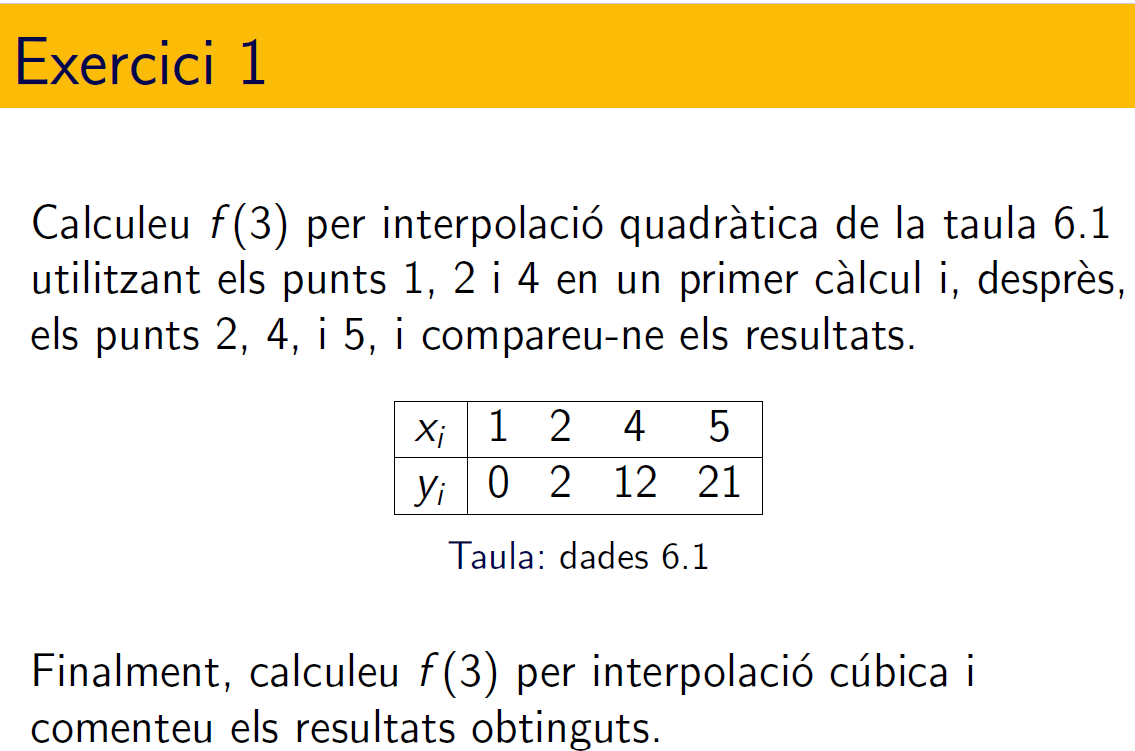

Aquest exercici s'ha de resoldre contruint la matriu de [**Vandermonde**](https://es.mathworks.com/help/matlab/ref/vander.html)

- primer càlcul

x = [1 2 4]; y = [0 2 12];
disp([x',y'])

     1     0
     2     2
     4    12



V = vander(x); coeff = linsolve(V,y')

coeff =      1
    -1
     0


valor = polyval(coeff,3);       % polinomi i valor a calcular
disp(['valor =',num2str(valor)])

valor =6


- segon  càlcul

x = [2 4 5]; y = [2 12 21];
disp([x',y'])

     2     2
     4    12
     5    21



V = vander(x); coeff = linsolve(V,y')

coeff =        1.3333
           -3
       2.6667


valor = polyval(coeff,3);      % polinomi i valor a calcular
disp(['valor = ',num2str(valor)])

valor = 5.6667


- tercer  càlcul

x = [ 1 2 4 5]; y = [0 2 12 21];
disp([x',y'])

     1     0
     2     2
     4    12
     5    21



V = vander(x); coeff = linsolve(V,y')

coeff =      0.083333
      0.41667
      0.16667
     -0.66667


valor = polyval(coeff,3);      % polinomi i valor a calcular
disp(['valor = ',num2str(valor)])

valor = 5.8333


### Exercici 2

### 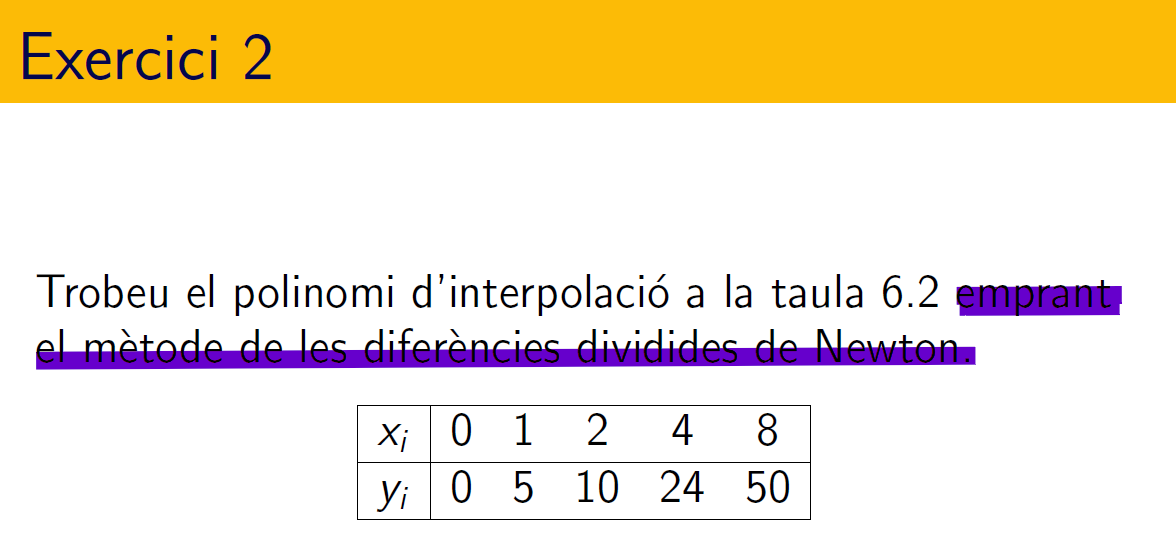

x = [0 1 2 4 8]; y = [0,5 10 24 50];
disp([x; y])

     0     1     2     4     8
     0     5    10    24    50



V = vander(x); p = linsolve(V,y')            % polinomi a calcular

p =     -0.034226
      0.40625
     -0.97917
       5.6071
            0


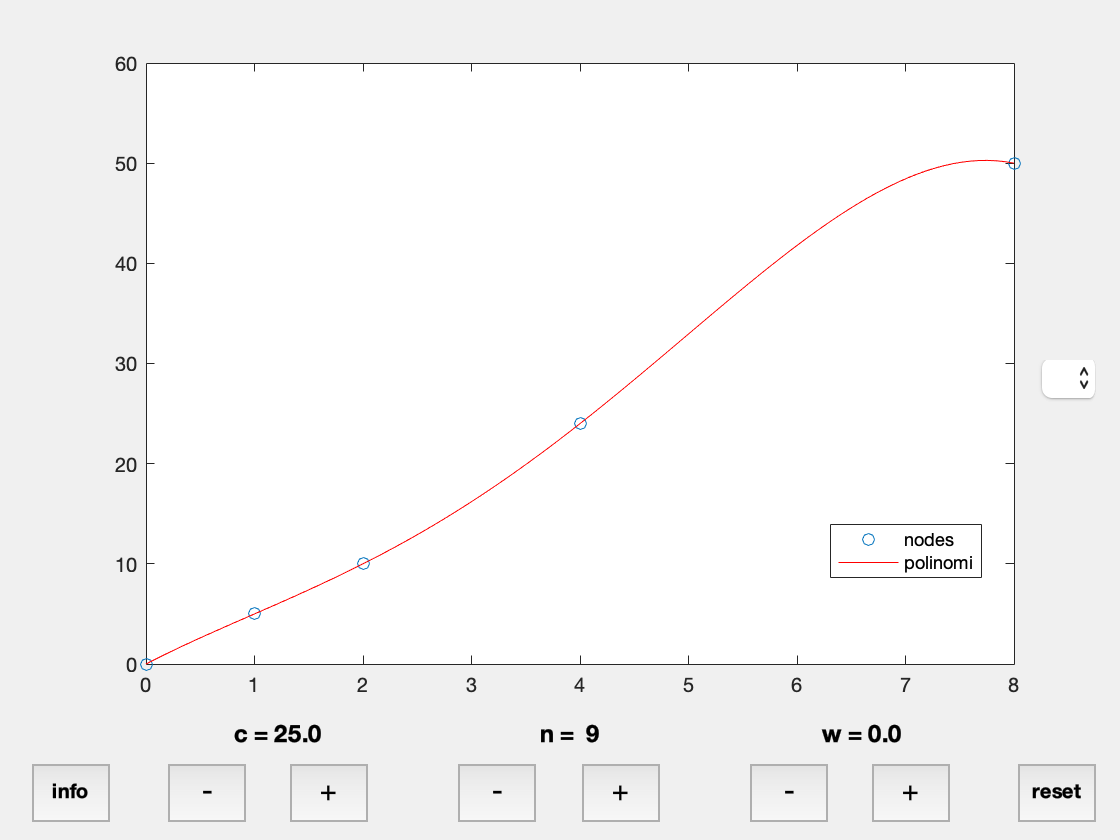

u = linspace(x(1),x(end));
v = polyval(p,u);
plot(x,y,'o',u,v,'r-'); legend('nodes','polinomi','Location','best')

### Exercici 3

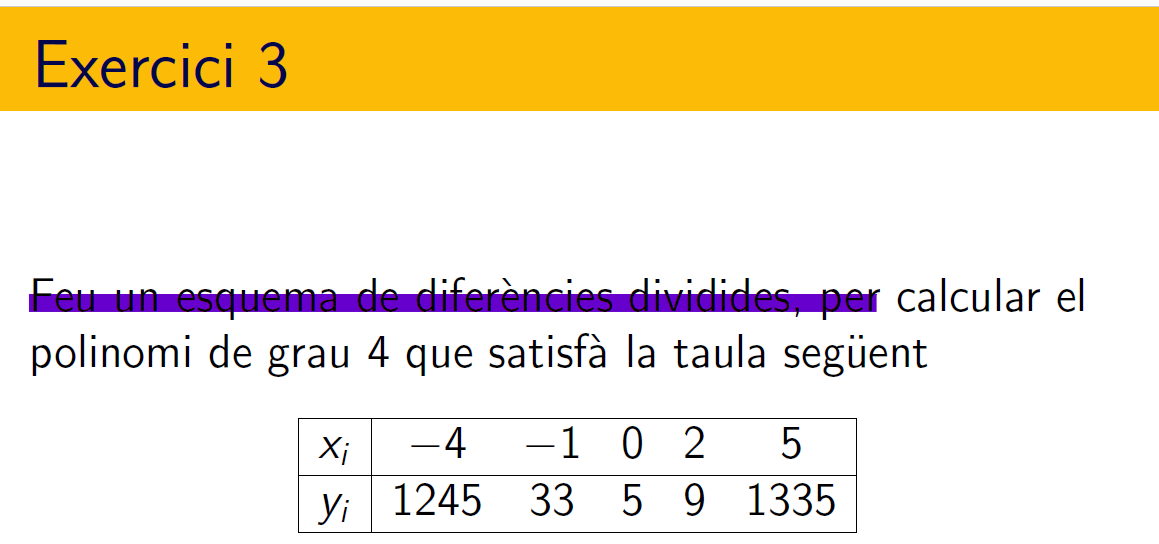

x = [-4 -1 0 2 5]; y = [1245 33 5 9 1335];
disp([x; y])

          -4          -1           0           2           5
        1245          33           5           9        1335



grau = length(x)-1

grau =      4


p = polyfit(x,y,grau)

p =             3           -5            6          -14            5


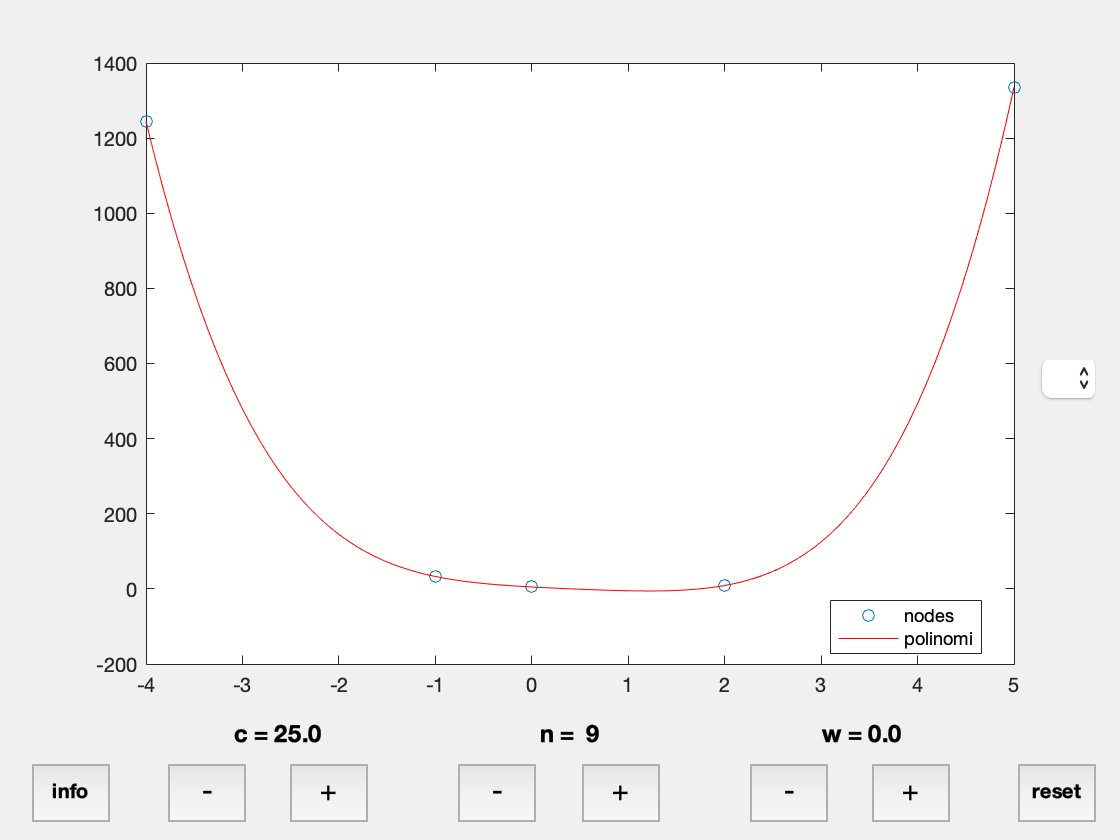

u = linspace(x(1),x(end));
v = polyval(p,u);
plot(x,y,'o',u,v,'r-'); legend('nodes','polinomi','Location','best')

### Exercici 4

## 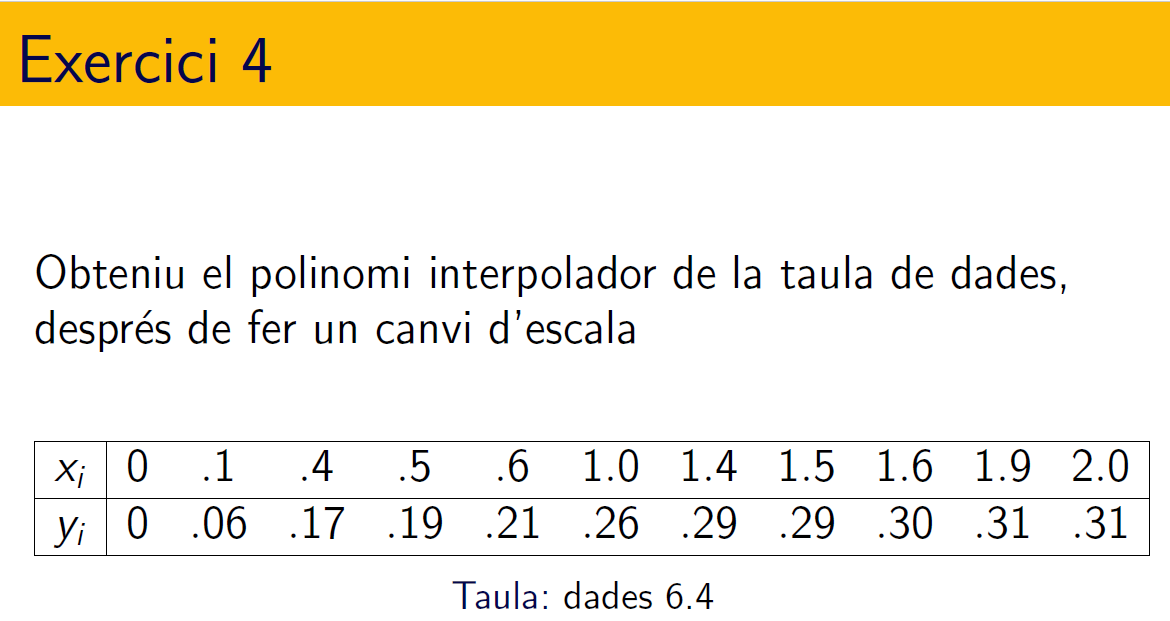


x = [0 .1 .4 .5 .6 1.0 1.4 1.5 1.6 1.9 2.0];
y = [0 .06 .17 .19 .21 .26 .29 .29 .30 .31 .31];
disp([x; y])

            0          0.1          0.4          0.5          0.6            1          1.4          1.5          1.6          1.9            2
            0         0.06         0.17         0.19         0.21         0.26         0.29         0.29          0.3         0.31         0.31



disp('coeficients sense canvi escala')

coeficients sense canvi escala


%----------------------------
grau = length(x)-1;
p = polyfit(x,y,grau);
u = 0:.05:2;
v1 = polyval(p,u);
%----------------------------
v2 = interp1(x, y, u);
%----------------------------
v3 = interp1(x, y, u, 'spline');

- Obteniu el polinomi interpolador, fent ús de **polyfit**

- Obteniu un spline lineal, fent ús de **interp1 i lineal**

- Obteniu un spline cúbic, fent ús de **interp1 i spline**

- Feu una representació gràfica de les dades, el polinomi i els splines

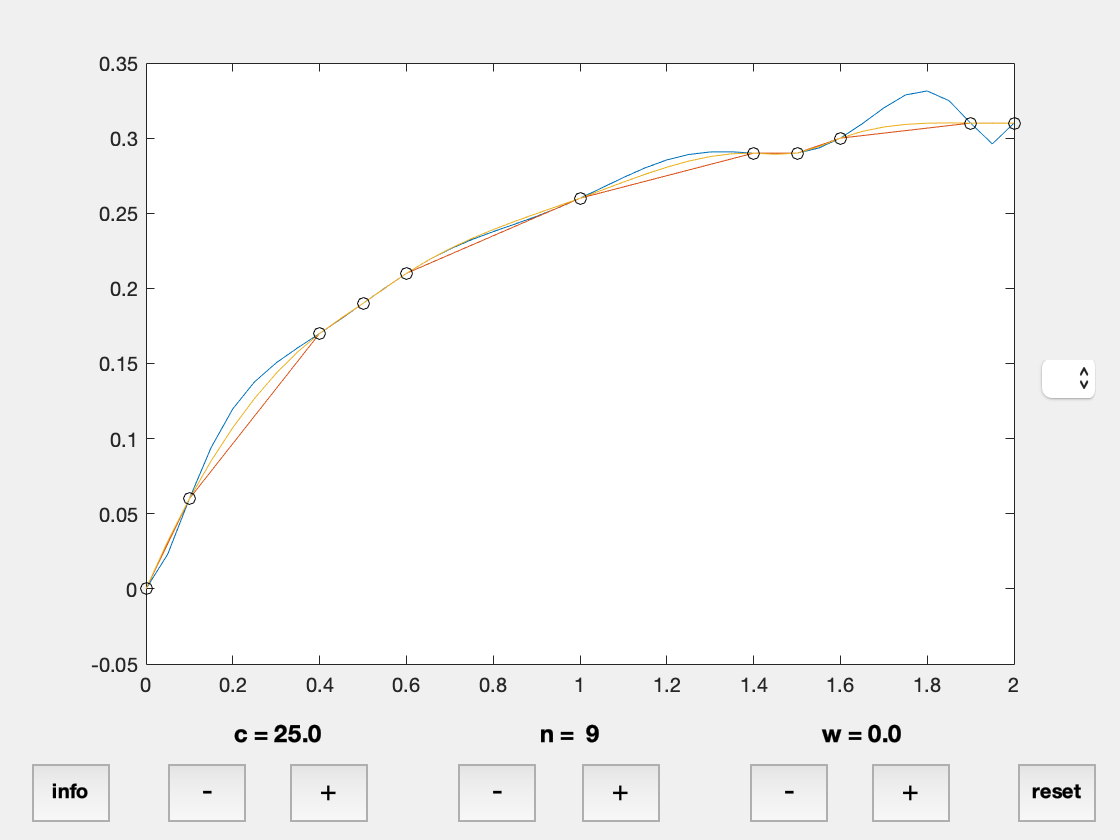


plot(u,v1, u, v2, u,v3, x, y, "ko")


disp('coeficients amb canvi escala')

coeficients amb canvi escala


### Exercici 5

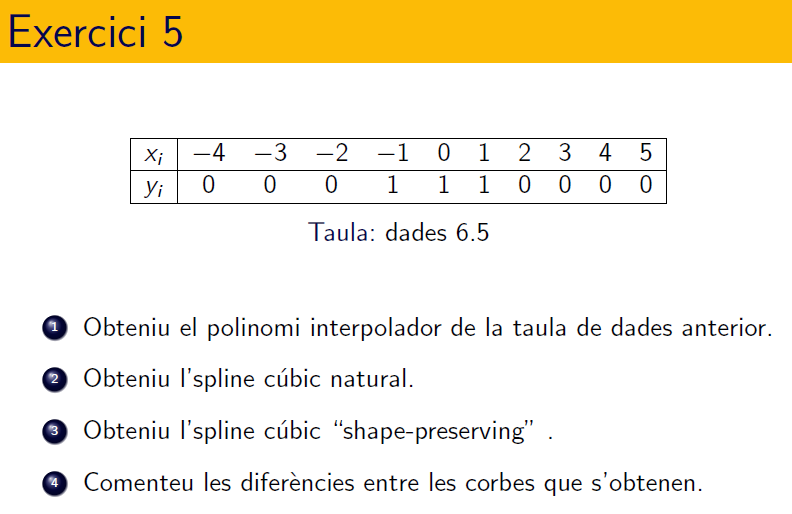

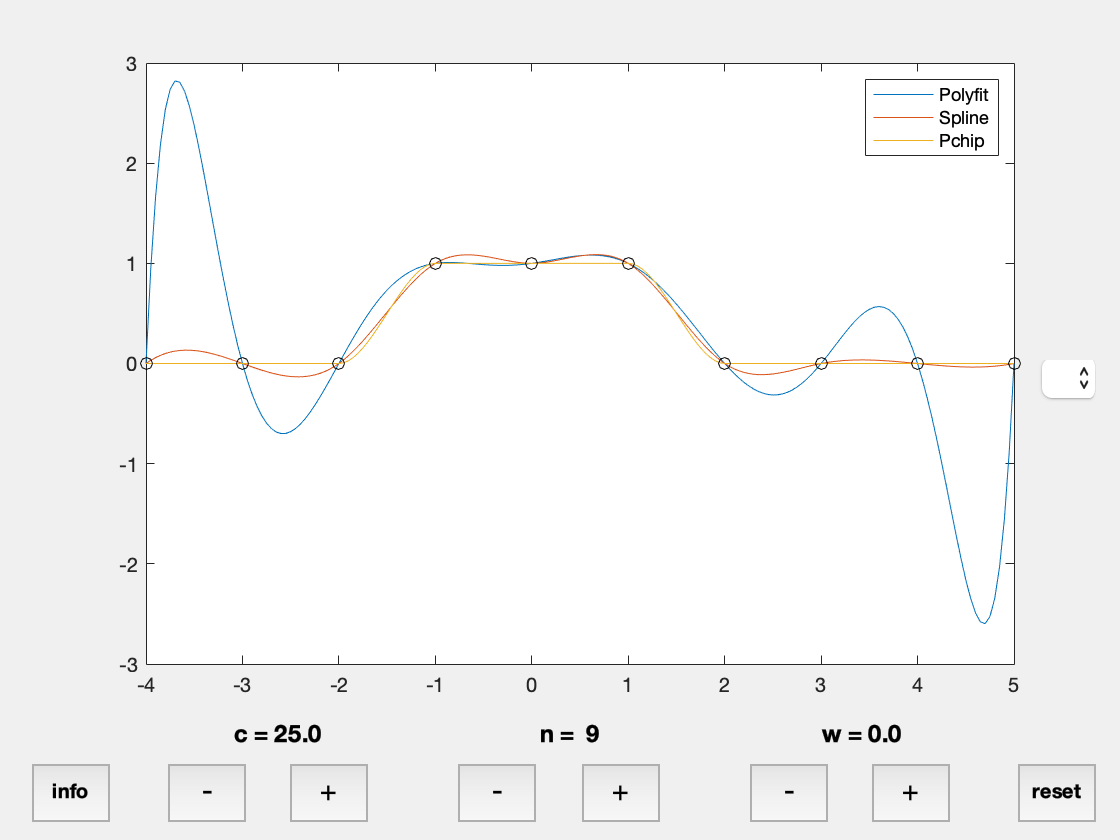

x = -4:1:5;
y = [0 0 0 1 1 1 0 0 0 0];
%----------------------------
grau = length(x)-1;
p = polyfit(x,y,grau);
u = -4:.05:5;
v1 = polyval(p,u);
%----------------------------
v2 = interp1(x, y, u, 'spline');
%----------------------------
v3 = interp1(x, y, u, 'pchip');

plot(u,v1, u, v2, u,v3, x, y, "ko")
legend('Polyfit', 'Spline', 'Pchip')

### Exercici 6

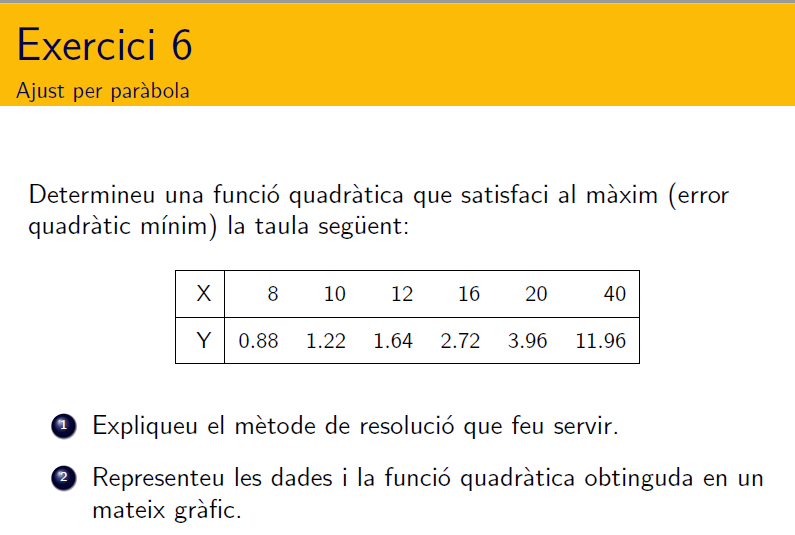

%està a la entrega de la L5 Segona Part quan hem d'escollir el millor
%polinomi (però a priori sembla que fent un ajustament amb una paràbola
%hauria de funcionar) funciona si

clearvars;
x=[8,10,12,16,20,40] 

x =      8    10    12    16    20    40


y=[0.88,1.22,1.64,2.72,3.96,11.96];

r = polyfit(x,y,1)

r =        0.3539      -2.5222


p = polyfit(x,y,2)

p =     0.0045322      0.13075     -0.51665


c = polyfit(x,y,3)

c =   -0.00012301      0.01279    -0.023389      0.30418


grau4 = polyfit(x,y,4)

grau4 =     9.382e-06  -0.00088321     0.033166     -0.24285       1.1156


grau5 = polyfit(x,y,5)

grau5 =    1.7764e-06  -0.00015891    0.0049295    -0.060022      0.45699     -0.86571


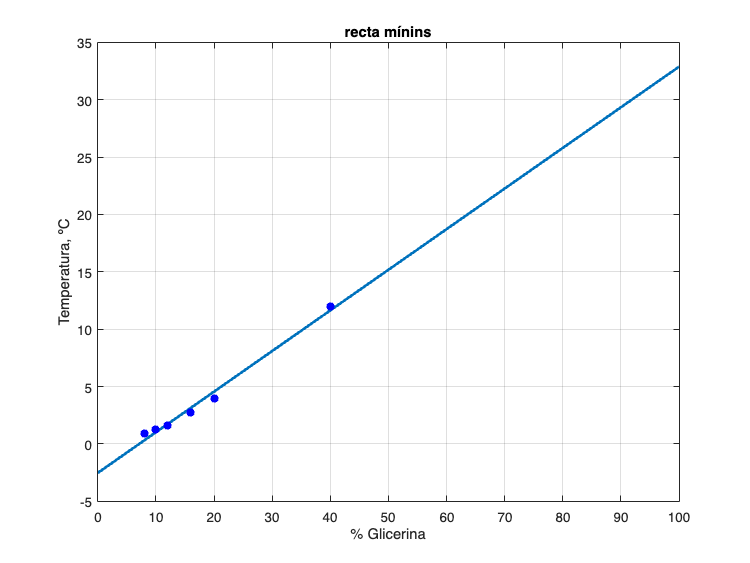


%labels inventats d'alguna practica anterior
z  = [0:100]; 
pz = polyval(r,z);
plot(z,pz,x,y,'*b','LineWidth',2)
grid on
ylabel('Temperatura, ºC')
xlabel('% Glicerina')
title('recta mínins')
hold off

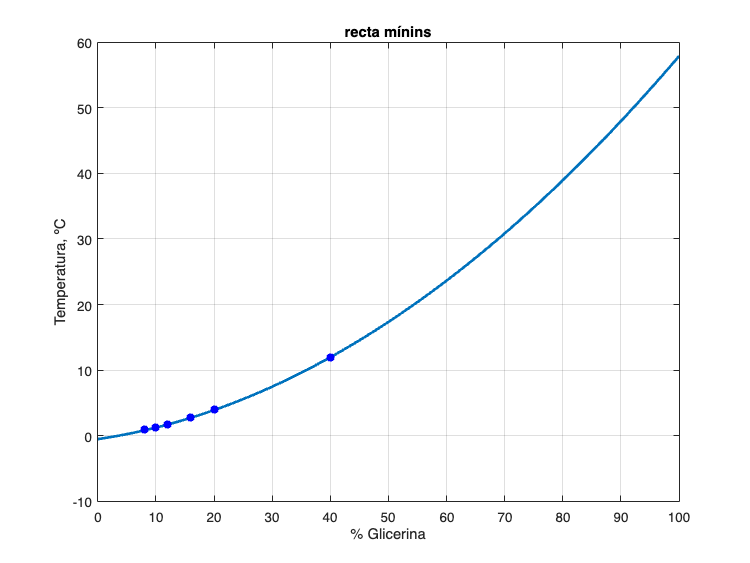


z  = [0:100]; 
pz = polyval(p,z);
plot(z,pz,x,y,'*b','LineWidth',2)
grid on
ylabel('Temperatura, ºC')
xlabel('% Glicerina')
title('recta mínins')
hold off

### Pràctica: Interpolació inversa

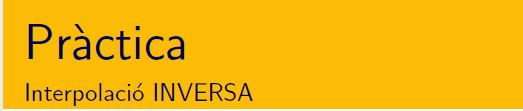

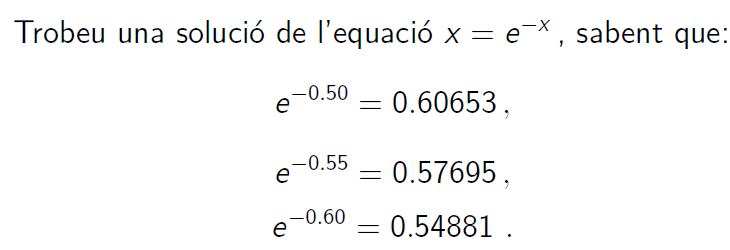

f=@(x)x-exp(-x)

f = function_handle with value:
    @(x)x-exp(-x)

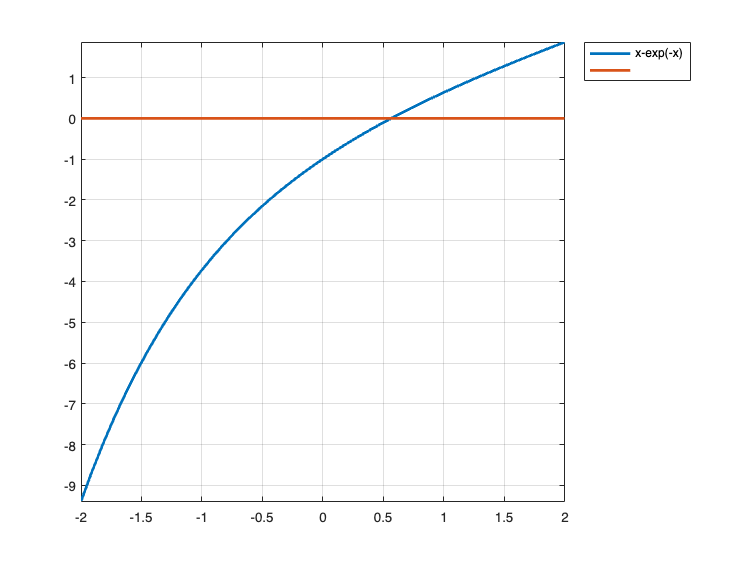

fplot({f,0},[-2,2],'LineWidth',2),grid,legend('Location','bestoutside')


arrel = fzero(f,1)

arrel =       0.56714


xnodes = [0.5:0.1:0.75];
ynodes = f(xnodes);
disp([xnodes;ynodes]) % Pel teorema de Bolzano sabem que l'arrel està entre 0.5 y 0.75

          0.5          0.6          0.7
     -0.10653     0.051188      0.20341



alpha = polyinterp(ynodes, xnodes,0) % En quin punt volem calcular f(x) = 0

alpha =       0.56714


comparacio = abs(alpha-arrel)

comparacio =    1.2113e-06


arrel = interp1(ynodes,xnodes,0,'pchip')

arrel =       0.56715

p_arrel = polyfit(ynodes,xnodes,2); 
arrel = polyval(p_arrel,0)

arrel =       0.56714

### Pràctica: Comportament de l'error en la interpolació polinòmica

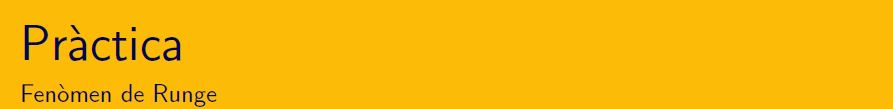

Baixeu-vos del campus el codi de rungeinterp.m. Aquest codi és el que C. Moler explica en el chapter 3 dels seus apunts *"Numerical Computing with Matlab". *Consulteu l'exercici 3.9 de la pàgina 23. 

a) Experimenteu la interpolació de la funció f(x) per n=2,3,7,11,13,17,19,23,29 ... o altres valors en punts equiespaiats fent ús de rungeinterp.m i polyinterp.m

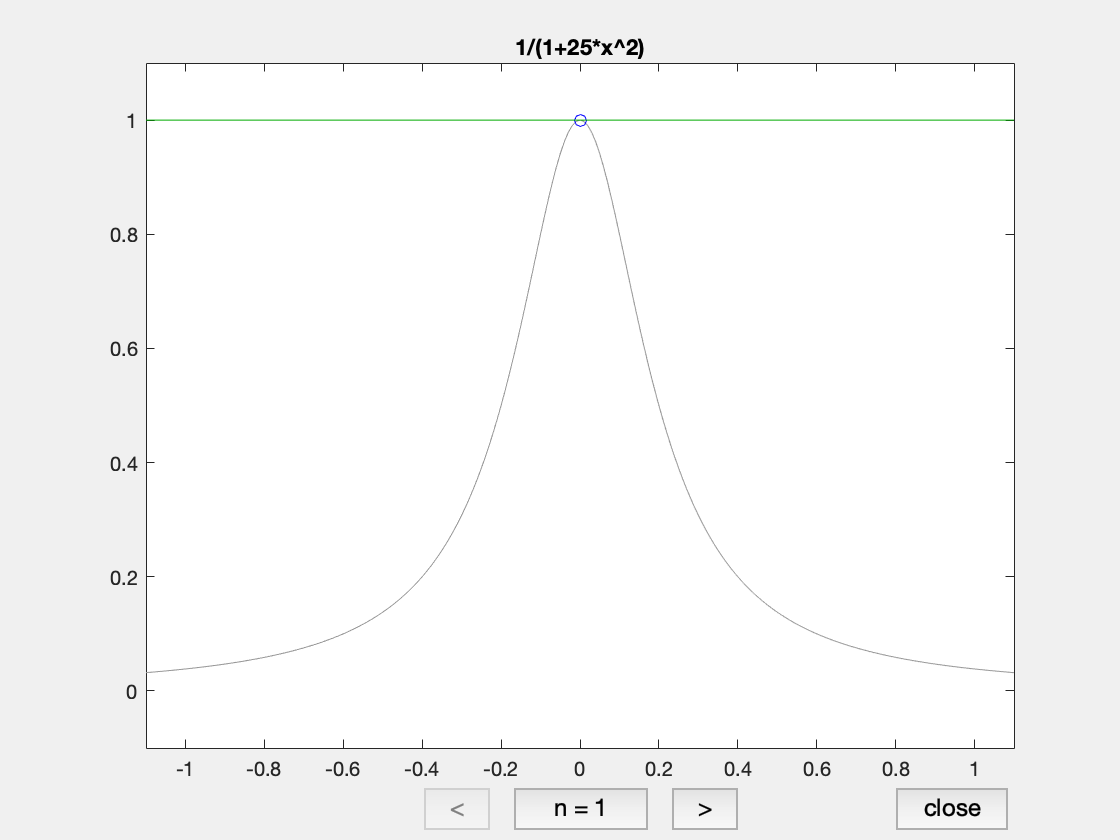

%explicat a classe dimarts 27Abril
rungeinterp()

Responeu: Per a quins x de l'interval [-1,1] és compleix $P_n(x) \rightarrow f(x)$ per $n \rightarrow \infty$?

b) Experimenteu la interpolació de la funció f(x) per n=2,3,7,11,13,17,19,23,29 ... o altres valors fent en punts no EQUIESPAIATS fent ús de interp_gadget.m i polyinterp.m

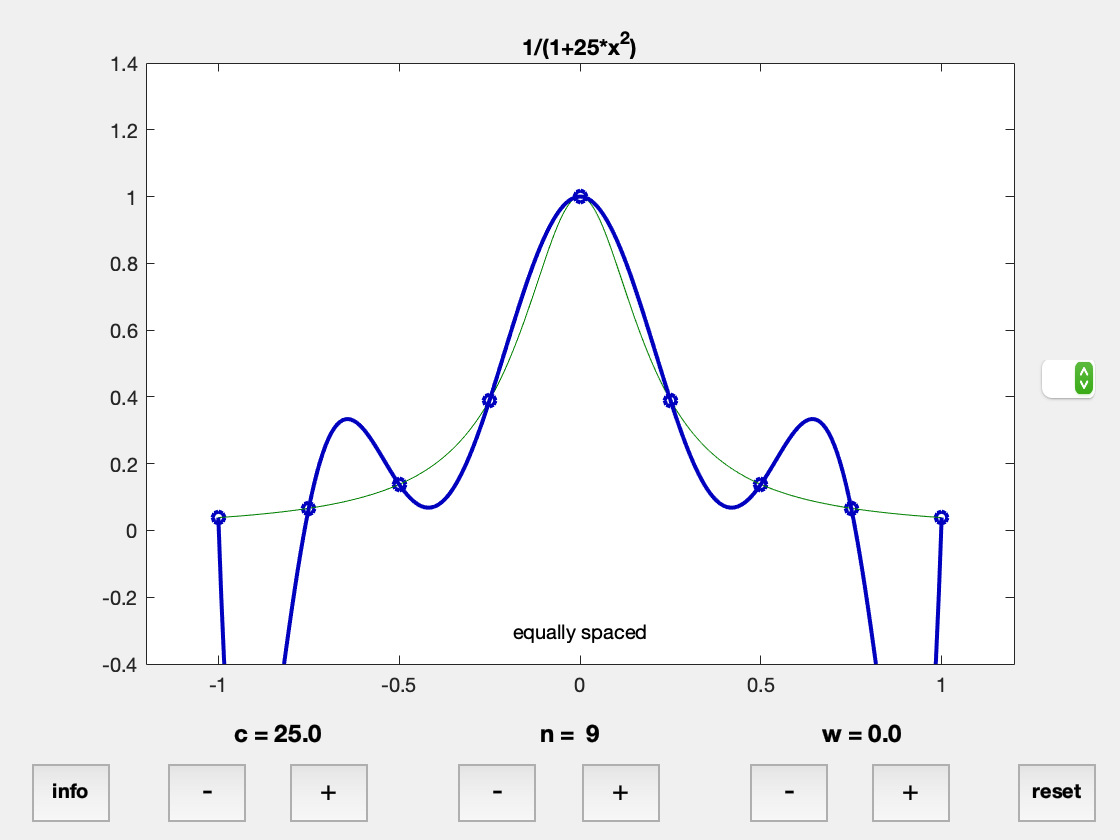

interp_gadget()

Responeu: Per a quin tipus d'abscises és compleix $P_n(x) \rightarrow f(x)$ per $n \rightarrow \infty$ per a tot x de l'interval [-1,1] ?

### Pràctica:  Corba amb millor ajust

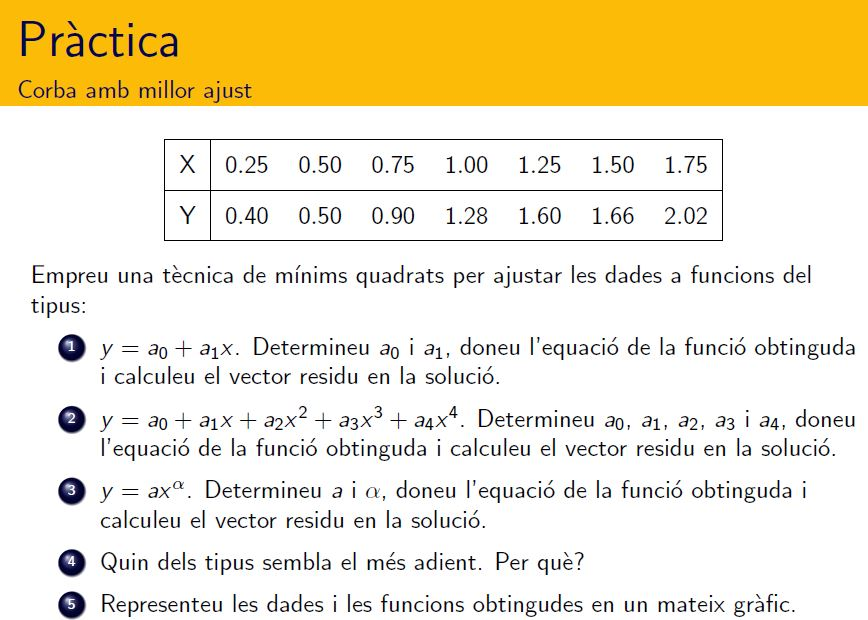

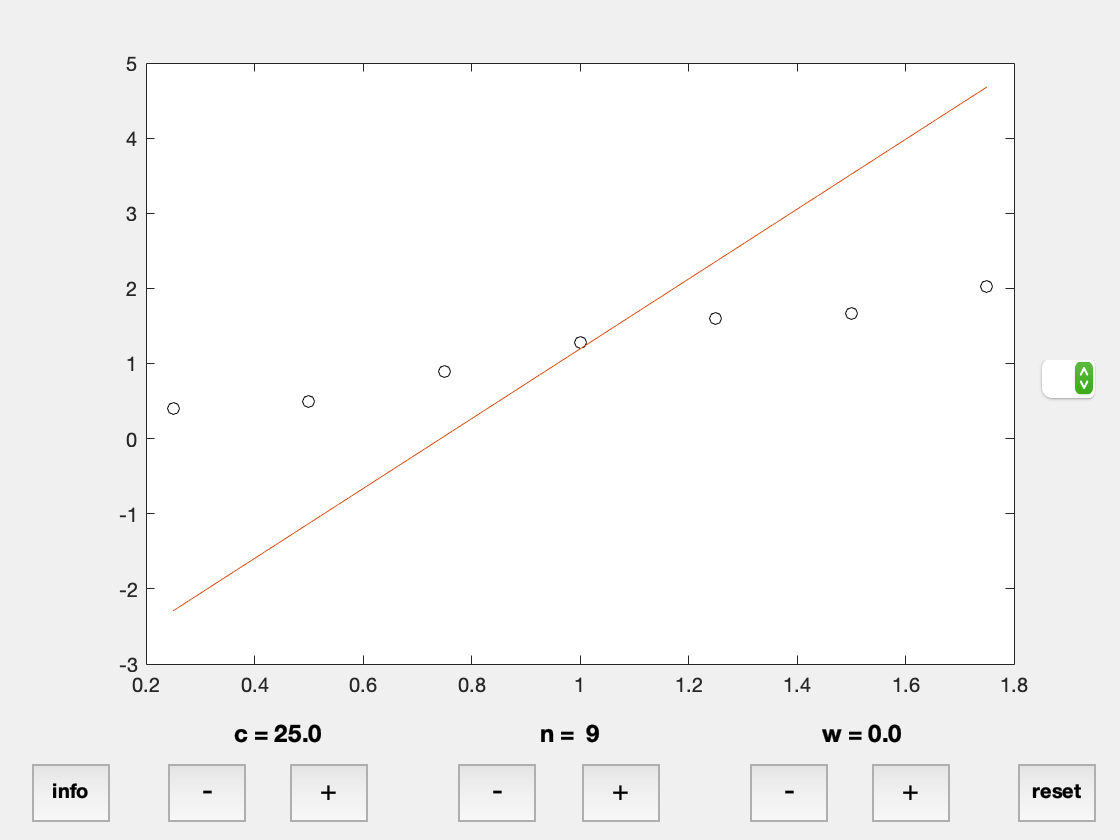

%no estic massa segura d'això
x = [0.25 0.50 0.75 1.00 1.25 1.50 1.75];
y = [0.40 0.50 0.90 1.28 1.60 1.66 2.02];
xy = x .* y;
x2 = x .* x;

m = (sum(xy) - (sum(x) + sum(y)) / length(x)) / (sum(x2) - (sum(x)^2/length(x)));
b = mean(y)-(m*mean(x));
func = @(x) m.*x + b;
plot(x, y, 'ko', x, func(x))

### 3 Codi funcions: polyinterp 

Baixeu-vos del campus el codi de polyinterp.m. Aquest codi és el que C. Moler explica en el chapter 3 dels seus apunts *"Numerical Computing with Matlab"  (*pàgina 5). 

La rutina polyinterp.m obté els valors del polinomi interpolador (fórmula de Lagrange) de la taula [x;y] i permet fer la seva representació gràfica. En cap cas obtenim els coeficients del polinomi interpolador. 

function v = polyinterp(x,y,u)
%POLYINTERP  Polynomial interpolation.
%   v = POLYINTERP(x,y,u) computes v(j) = P(u(j)) where P is the
%   polynomial of degree d = length(x)-1 with P(x(i)) = y(i).

%   Copyright 2014 Cleve Moler
%   Copyright 2014 The MathWorks, Inc.

% Use Lagrangian representation.
% Evaluate at all elements of u simultaneously.

n = length(x);
v = zeros(size(u));
for k = 1:n
   w = ones(size(u));
   for j = [1:k-1 k+1:n]
      w = (u-x(j))./(x(k)-x(j)).*w;
   end
   v = v + w*y(k);
end
end

function interp_gadget(callbak,~)
% Explore the Runge phenomenon -- does polynomial interpolation converge?
% The f popup chooses among three functions:
%    f(x) = 1/(1+c*x^2),
%    f(x) = exp(-c*x*2),
%    f(x) = abs(c*x).
% The + and - buttons increment or decrement three parameters:
%    c: coefficient of x^2,
%    n: number of interpolation points,
%    w: weighted average of equally spaced and Chebyshev points.
% As n increases, does the polynomial interpolant converge to f(x)?
%
% References:
%    Cleve's Corner: https://blogs.mathworks.com/cleve/2018/12/10
%    Wikipedia: https://en.wikipedia.org/wiki/Runge's_phenomenon
%   Copyright 2018 Cleve Moler
%   Copyright 2018 The MathWorks, Inc.
    if nargin == 0 || isequal(get(callbak,'string'),'reset')
        
        % Initialize
        
        c = 25;   % Coefficient in 1/(1+c*x^2) or exp(-c*x^2).
        n = 9;    % Number of interpolation points.
        w = 0.0;  % Weight between equal and Chebyshev spacing.
        
        x = -1:2/(n-1):1;  % Interpolation points.
        u = -1:1/128:1;    % Plot sampling points.     
        
        p = plots(x,u);    
        b = buttons;
        q = labels(c,n,w);
        callbak = false;
        set(gcf,'userdata',{c,n,w,p,q,b,u})
        
    else
             
        % Callbacks
        
        ud = get(gcf,'userdata');
        [c,n,w,p,q,b,u] = deal(ud{:});
        
    end
    
    % Update parameters
    
    [c,n,w] = update(c,n,w,b,q,callbak);
    
    % Which function?
    
    switch get(b(7),'value')
        case {1,2}
            f = @(x) 1./(1+c*x.^2);
        case 3
            f = @(x) exp(-c*x.^2);
        case 4
            f = @(x) abs(c*x);
    end
    
    % Interpolation points
    
    xeq = -1:2/(n-1):1;
    xch = cos((n-1/2:-1:1/2)/n*pi);
    x = (1-w)*xeq + w*xch;
    
    % Polynomial interpolation
    % Interpolate f(x), sampled at x, evaluated at u.
    
    y = polyinterp(x,f(x),u);
    
    % Update plots
    
    set(p(1),'xdata',x,'ydata',f(x))  % Blue circles.
    set(p(2),'xdata',u,'ydata',f(u))  % Thin green line.
    set(p(3),'xdata',u,'ydata',y)     % Interpolant, heavy blue line.
    update_caption(p(4),w,c)
    update_title(p(5),f,c)
    
    % Save parameters and handles
    
    set(gcf,'userdata',{c,n,w,p,q,b,u})
    
% -------------------------------------------------------------
    function p = plots(x,u)
        % Initialize three plots, caption and title.
        clf
        shg
        pos = [.1300 .2100 .7750 .7150];
        ax = axes('position',pos);
        p = plot(x,0*x,'o', ...
                 u,0*u,'-', ...
                 u,0*u,'-');
        set(p(1),'color',[0 0 0.75],'linewidth',2)  % Dark blue
        set(p(2),'color',[0 0.5 0])   % Dark green
        set(p(3),'color',get(p(1),'color'),'linewidth',2)
        set(ax,'xlim',[-1.2 1.2],'ylim',[-.4 1.4])
        p(4) = text(0.0,-0.3,'','horiz','center');  % Caption
        p(5) = title('');
    end % plots
    function b = buttons
        % Initialize six +/- pushbuttons, 'f' popup, ...
        % and info and reset buttons.
        
        b = zeros(1,6);
        for k = 1:6 
            if mod(k,2) == 1
                xp = .13*k+.02;
                s = '-';
            else
                xp = .13*k;
                s = '+';
            end
            b(k) = uicontrol('style','pushbutton', ...
                'units','normalized', ...
                'position',[xp,.02,.07,.07], ...
                'string',s, ... 
                'fontsize',14, ...
                'callback',@interp_gadget);
        end
        
        % Select function
        flist = {'f','1/(1+c*x^2','exp(-c*x^2)','abs(c*x)'};
        b(7) = uicontrol('style','popup', ...
            'units','normalized', ...
            'position',[.92,.50,.07,.07], ...
            'string',flist, ...
            'fontsize',10, ...
            'fontweight','bold', ...
            'callback',@interp_gadget); 
        
        % info button
        
        infocb = @(~,~) ...
             web('http://blogs.mathworks.com/cleve/2018/12/10');
        uicontrol('style','pushbutton', ...
            'units','normalized', ...
            'position',[.03,.02,.07,.07], ...
            'string','info', ... 
            'fontsize',10, ...
            'fontweight','bold', ...
            'callback',infocb);
        
        % reset button
        
        uicontrol('style','pushbutton', ...
            'units','normalized', ...
            'position',[.91,.02,.07,.07], ...
            'string','reset', ... 
            'fontsize',10, ...
            'fontweight','bold', ...
            'callback',@interp_gadget);
    end % buttons
    function q = labels(c,n,w)
        % Initialize three labels.
        q = zeros(1,3);
        for k = 1:3
            if k == 1
                s = sprintf('c = %3.1f',c);
            elseif k == 2
                s = sprintf('n = %2d',n);
            else
                s = sprintf('w = %2.1f',w);
            end
            q(k) = uicontrol('style','text', ...
                'units','normalized', ...
                'position',[.26*k-.08,.10,.14,.05], ...
                'string',s, ...
                'fontsize',12, ...
                'fontweight','bold');    
        end     
    end % labels
 
    function [c,n,w] = update(c,n,w,b,q,callbak)
        % Respond to callback.
        switch callbak
            case b(1)
                c = c-delc(b);
            case b(2)
                c = c+delc(b);
            case b(3)
                n = n-1;
            case b(4)
                n = n+1;
            case b(5)
                w = w-0.1;
            case b(6)
                w = w+0.1;
            case b(7)
                if get(b(7),'value') < 4
                    c = 25;
                else
                    c = 1;
                end
        end
        set(q(1),'string',sprintf('c = %3.1f',c));
        set(q(2),'string',sprintf('n = %2.0f',n));
        set(q(3),'string',sprintf('w = %2.1f',w));
    end % update
    function del = delc(b)
        if get(b(7),'value') < 4
            del = 1;
        else 
            del = .1;
        end
    end % delc
    function update_caption(caption,w,c)
        if abs(w) < eps
            s = 'equally spaced';
        elseif abs(1-w) < eps
            s = 'chebyshev';
        elseif w < 1
            s = sprintf('%2.1f*cheby + %2.1f*equal',w,1-w);
        else
            s = sprintf('%2.1f*cheby - %2.1f*equal',w,w-1);
        end
        if c > 0
            ypos = -0.3;
            set(gca,'ylim',[-0.4 1.4])
        else
            ypos = -7;
            set(gca,'ylim',[-8 10])
        end
        set(caption,'string',s,'position',[0.0 ypos 0.0])
    end % update_caption
    function update_title(titl,f,c)
        F = func2str(f);
        F = F(5:end);  % Remove leading '(x)'.
        F = regexprep(F,'\.',''); % Remove dots.
        if c == 0
            s = '1';
        elseif c == 1
            s = regexprep(F,'c\*','');
        elseif c > 0
            if c >= 10
                form = regexprep(F,'c','%2.0f');
            else
                form = regexprep(F,'c','%3.1f');
            end
            s = sprintf(form,c);
        elseif c == -1 && any(F=='-')
            s = regexprep(F,'-c\*','');
        elseif c == -1   
            s = regexprep(F,'+c\*','-');
        elseif any(F=='-')
            form = regexprep(F,'-c','%2.0f');
            s = sprintf(form,-c);
        else
            if c <= -10
                form = regexprep(F,'c','%2.0f');
            else
                form = regexprep(F,'c','%3.1f');
            end
            s = sprintf(form,-c);
        end
        set(titl,'string',s)   
    end % update_title
    function v = polyinterp(x,y,u)
        %POLYINTERP  Polynomial interpolation.
        %   v = POLYINTERP(x,y,u) computes v(j) = P(u(j)) where P is the
        %   polynomial of degree d = length(x)-1 with P(x(i)) = y(i).
        % Use Lagrangian representation.
        % Evaluate at all elements of u simultaneously.
        n = length(x);
        v = zeros(size(u));
        for k = 1:n
           z = ones(size(u));
           for j = [1:k-1 k+1:n]
              z = (u-x(j))./(x(k)-x(j)).*z;
           end
           v = v + z*y(k);
        end
    end % polyinterp
end % interp_gadget

function rungeinterp(arg)
%RUNGEINTERP  Runge's polynomial interpolation example.
%   F(x) = 1/(1+25*x^2)
%   Polynomial interpolation at equally spaced points, -1 <= x <= 1.
%   Does interpolant converge as number of points is increased?

%   Copyright 2014 Cleve Moler
%   Copyright 2014 The MathWorks, Inc.


if nargin == 0

   % Initialize plot and uicontrols

   shg
   clf reset
   set(gcf,'numbertitle','off','menu','none', ...
       'name','Runge''s interpolation example')
   n = 1;
   u = -1.1:.01:1.1;
   z = rungerat(u);
   h.plot = plot(u,z,'-', 0,1,'o', u,z,'-');
   set(h.plot(1),'color',[.6 .6 .6]);
   set(h.plot(2),'color','blue');
   set(h.plot(3),'color',[0 2/3 0]);
   axis([-1.1 1.1 -0.1 1.1])
   title('1/(1+25*x^2)','interpreter','none')

   h.minus = uicontrol('units','norm','pos',[.38 .01 .06 .05], ...
          'fontsize',12,'string','<','callback','rungeinterp(''n--'')');
   h.n = uicontrol('units','norm','pos',[.46 .01 .12 .05], ...
          'fontsize',12,'userdata',n,'callback','rungeinterp(''n=1'')');
   h.plus = uicontrol('units','norm','pos',[.60 .01 .06 .05], ...
          'fontsize',12,'string','>','callback','rungeinterp(''n++'')');
   h.close = uicontrol('units','norm','pos',[.80 .01 .10 .05], ...
          'fontsize',12,'string','close','callback','close');

   set(gcf,'userdata',h)
   arg = 'n=1';
end

% Update plot.

h = get(gcf,'userdata');

% Number of interpolation points.

n = get(h.n,'userdata');
switch arg
   case 'n--', n = n-2;
   case 'n++', n = n+2;
   case 'n=1', n = 1;
end
set(h.n,'string',['n = ' num2str(n)],'userdata',n);
if n==1
   set(h.minus,'enable','off');
else
   set(h.minus,'enable','on');
end

if n == 1;
   x = 0;
else
   x = -1 + 2*(0:n-1)/(n-1);
end
y = rungerat(x);
u = get(h.plot(1),'xdata');
v = polyinterp(x,y,u);
set(h.plot(2),'xdata',x,'ydata',y);
set(h.plot(3),'xdata',u,'ydata',v);
end
% ------------------------

function y = rungerat(x);
y = 1./(1+25*x.^2);
end
